# sound evoked AC thresholds

% P13-P14 control and Cx26 cKO

noAtten = [102 105 107 103 104 103 102 100 110 109 110 110 108];
Atten10 = noAtten - 10;
Atten20 = noAtten - 20;
Atten30 = noAtten - 30;
Atten40 = noAtten - 40;
Atten50 = noAtten - 50;
Atten60 = noAtten - 60;
Atten70 = noAtten - 70;

attenMatx = [noAtten;Atten10;Atten20;Atten30;Atten40;Atten50;Atten60;Atten70];

cko1db0 = [0 0 0 0 1 1 1 0 1 1 0 0 0]; %397-1
cko1db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
cko1db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko2db0 = [0 0 0 0 1 1 1 1 1 1 1 1 0]; %397-2 
cko2db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko2db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko3db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 412-1
cko3db20 = [0 0 0 0 0 1 1 1 1 1 0 0 0]; 
cko3db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko4db0 = [1 0 0 1 1 1 1 1 1 1 1 0 0]; % 419-2
cko4db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
cko4db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko5db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 432-2
cko5db20 = [0 0 0 0 0 0 0 0 1 0 0 0 0]; 
cko5db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko6db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 444-1
cko6db10 = [1 1 0 1 1 1 1 1 1 1 1 0 0]; 
cko6db20 = [0 0 0 0 0 1 1 0 1 0 0 0 0]; 
cko6db30 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
cko6db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko7db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 444-3
cko7db10 = [1 1 1 1 1 1 1 1 1 1 0 0 0]; 
cko7db20 = [0 0 0 1 1 1 0 0 1 1 0 0 0]; 
cko7db30 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
cko7db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

threshCko1 = getThresh(cko1db0,cko1db20,cko1db40)

threshCko1 =    102   105   107   103    94    93    92   100   100    99   110   110   108


threshCko2 = getThresh(cko2db0,cko2db20,cko2db40)

threshCko2 =    102   105   107   103    94    93    92    90   100    99   100   100   108


threshCko3 = getThresh(cko3db0,cko3db20,cko3db40)

threshCko3 =     92    95    97    93    94    73    72    70    80    79   100   100    98


threshCko4 = getThresh(cko4db0,cko4db20,cko4db40)

threshCko4 =     92   105   107    93    94    93    92    90   100    99   100   110   108


threshCko5 = getThresh(cko5db0,cko5db20,cko5db40)

threshCko5 =     92    95    97    93    94    93    92    90    80    99   100   100   108


threshCko6 = getThresh5files5step(cko6db0,cko6db10,cko6db20,cko6db30,cko6db40)

threshCko6 =     87    90   102    88    89    78    77    85    85    94    95   105   108


threshCko7 = getThresh5files5step(cko7db0,cko7db10,cko7db20,cko7db30,cko7db40)

threshCko7 =     87    90    92    78    79    78    87    85    85    84   105   105   108


ckoMean = mean([threshCko1;threshCko2;threshCko3;threshCko4;threshCko5;threshCko6;threshCko7;],1);
ckoSTD = std([threshCko1;threshCko2;threshCko3;threshCko4;threshCko5;threshCko6;threshCko7;],1);

conditions = {'4.5 kHz','9.5 kHz','15 kHz','24 kHz','38 kHz'};
cko3 = [threshCko1(1),threshCko2(1),threshCko3(1),threshCko4(1),threshCko5(1),threshCko6(1),threshCko7(1)];
cko6 = [threshCko1(3),threshCko2(3),threshCko3(3),threshCko4(3),threshCko5(3),threshCko6(3),threshCko7(3)];
cko9_5 = [threshCko1(6),threshCko2(6),threshCko3(6),threshCko4(6),threshCko5(6),threshCko6(6),threshCko7(6)];
cko15 = [threshCko1(8),threshCko2(8),threshCko3(8),threshCko4(8),threshCko5(8),threshCko6(8),threshCko7(8)];
cko24 = [threshCko1(10),threshCko2(10),threshCko3(10),threshCko4(10),threshCko5(10),threshCko6(10),threshCko7(10)];
cko38 = [threshCko1(12),threshCko2(12),threshCko3(12),threshCko4(12),threshCko5(12),threshCko6(12),threshCko7(12)];
ckoMeanMatx = [threshCko1',threshCko2',threshCko3',threshCko4',threshCko5',threshCko6',threshCko7'];

con1db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 409-1 
con1db20 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 409-1 
con1db40 = [0 0 0 0 1 1 1 1 1 1 1 0 0]; 
con1db60 = [0 0 0 0 0 1 1 1 1 1 1 0 0]; 

con2db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 418-1
con2db20 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; 
con2db40 = [0 1 1 0 1 1 1 1 1 1 1 0 0]; % no 60 dB atten level, ugh

con3db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 418-3 
con3db20 = [1 1 1 1 1 1 1 1 1 1 0 0 0]; 
con3db40 = [0 1 0 0 0 1 1 1 1 1 0 0 0]; 
con3db60 = [0 0 0 0 0 1 0 0 0 0 0 0 0]; 

con4db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 432-3 
con4db20 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; 
con4db40 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; 
con4db60 = [0 0 0 1 1 1 1 1 1 1 1 0 0]; 

con5db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 444-2 
con5db20 = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con5db30 = [1 1 1 1 1 1 1 1 1 1 1 1 0];
con5db40 = [0 1 1 1 1 1 1 1 1 1 1 1 0];
con5db50 = [0 1 0 1 1 1 1 1 1 1 1 0 0];
con5db60 = [0 0 0 0 1 1 1 1 1 1 0 0 0];
con5db70 = [0 0 0 0 1 1 1 0 0 0 0 0 0];

threshCon1 = getThresh4files(con1db0,con1db20,con1db40,con1db60)

threshCon1 =     72    75    77    73    54    33    32    30    40    39    40    80   108


threshCon2 = getThresh(con2db0,con2db20,con2db40)

threshCon2 =     72    55    57    73    54    53    52    50    60    59    60    80    98


threshCon3 = getThresh4files(con3db0,con3db20,con3db40,con3db60)

threshCon3 =     72    55    77    73    74    33    52    50    60    59   100   100   108


threshCon4 = getThresh4files(con4db0,con4db20,con4db40,con4db60)

threshCon4 =     52    55    57    33    34    33    32    30    40    39    40    60    78


threshCon5 = getThresh5files5step(con5db30,con5db40,con5db50,con5db60,con5db70)-30

threshCon5 =     67    50    62    48    29    28    27    35    45    44    55    65    78


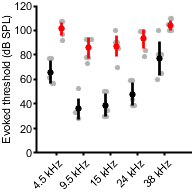


conMean = mean([threshCon1;threshCon2;threshCon3;threshCon4;threshCon5]); 
conSTD = std([threshCon1;threshCon2;threshCon3;threshCon4;threshCon5]); 

con3 = [threshCon1(1),threshCon2(1),threshCon3(1),threshCon4(1),threshCon5(1)];
con6 = [threshCon1(3),threshCon2(3),threshCon3(3),threshCon4(3),threshCon5(3)];
con9_5 = [threshCon1(6),threshCon2(6),threshCon3(6),threshCon4(6),threshCon5(6)];
con15 = [threshCon1(8),threshCon2(8),threshCon3(8),threshCon4(8),threshCon5(8)];
con24 = [threshCon1(10),threshCon2(10),threshCon3(10),threshCon4(10),threshCon5(10)];
con38 = [threshCon1(12),threshCon2(12),threshCon3(12),threshCon4(12),threshCon5(12)];
conMeanMatx = [threshCon1',threshCon2',threshCon3',threshCon4',threshCon5'];

figure
hold on

ylbl = 'Evoked threshold (dB SPL)';
dim = [2 2];
markSz = [17 17];
color1 = 'k';
color2 = 'r';
compare5offsetM(con6,con9_5,con15,con24,con38,conditions,ylbl,dim,markSz,color1,color1)
compare5offsetP(cko6,cko9_5,cko15,cko24,cko38,conditions,ylbl,dim,markSz,color2,color1)
ylim([0 120])


figure;
freq = [1:1:13]

freq =      1     2     3     4     5     6     7     8     9    10    11    12    13


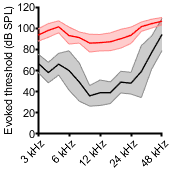

c = shadedErrorBar(freq,conMean,conSTD);
c.mainLine.LineWidth = 1;
c = shadedErrorBar(freq,ckoMean,ckoSTD,'lineprops','r');
c.mainLine.LineWidth = 1;
ylim([0 120])
xlim([1 13])
ylabel(ylbl,'FontSize',8);
xticks([1 4 7 10 13]);
xticklabels({'3 kHz','6 kHz','12 kHz','24 kHz','48 kHz'})
xtickangle([45])
figQuality(gcf,gca,[1.8 1.8])

%print(gcf,'-dpdf')

% linear mixed model 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5',};
mousecko = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11','12','13'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)',ckoMeanMatx(:,6)',ckoMeanMatx(:,7)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 156×4 table
    Genotype    Mouse     Location    BW 
    ________    ______    ________    ___

    {'con'}     {'M1'}     {'1' }      72
    {'con'}     {'M1'}     {'2' }      75
    {'con'}     {'M1'}     {'3' }      77
    {'con'}     {'M1'}     {'4' }      73
    {'con'}     {'M1'}     {'5' }      54
    {'con'}     {'M1'}     {'6' }      33
    {'con'}     {'M1'}     {'7' }      32
    {'con'}     {'M1'}     {'8' }      30
    {'con'}     {'M1'}     {'9' }      40
    {'con'}     {'M1'}     {'10'}      39
    {'con'}     {'M1'}     {'11'}      40
    {'con'}     {'M1'}     {'12'}      80
    {'con'}     {'M1'}     {'13'}     108
    {'con'}     {'M2'}     {'1' }      72
    {'con'}     {'M2'}     {'2' }      55
    {'con'}     {'M2'}     {'3' }      57


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml') 

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             156
    Fixed effects coefficients           2
    Random effects coefficients         25
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1186.7    1201.8    -588.33          1176.7  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)' }            57      4.5179    12.616    154    1.6428e-25    48.075    65.925
    {'Genotype_cko'}        37.736       4.566    8.2646    154    6.0518e-14    28.716    46.756

Random effects covariance parameters (95% CIs):
Group: Location (13 Levels)
    Name1                  Name2                  Type           

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    57.0000
   37.7363


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }            57      4.5179    12.616    19.665    7.0039e-11    47.565    66.435
    {'Genotype_cko'}        37.736       4.566    8.2646        10    8.8449e-06    27.563     47.91




% AC thresholds P10-P12

con1db0 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 393-2 
con1db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 393-2 
con1db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

con2db0 = [1 1 1 0 0 1 0 0 0 0 0 0 0]; % 394-1
con2db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
con2db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

con3db0 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 394-2
con3db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
con3db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

con4db0 = [1 0 0 0 0 0 0 0 0 0 0 0 0]; % 394-3 
con4db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 
con4db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

con5db0 = [1 1 1 0 0 1 0 0 0 0 0 0 0]; % 426-2
con5db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
con5db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

threshCon1 = getThresh(con1db0,con1db20,con1db40)

threshCon1 =    102   105   107   103   104   103   102   100   110   109   110   110   108


threshCon2 = getThresh(con2db0,con2db20,con2db40)

threshCon2 =     92    95    97   103   104    93   102   100   110   109   110   110   108


threshCon3 = getThresh(con3db0,con3db20,con3db40)

threshCon3 =    102   105   107   103   104   103   102   100   110   109   110   110   108


threshCon4 = getThresh(con4db0,con4db20,con4db40)

threshCon4 =     92   105   107   103   104   103   102   100   110   109   110   110   108


threshCon5 = getThresh(con5db0,con5db20,con5db40)

threshCon5 =     92    95    97   103   104    93   102   100   110   109   110   110   108




conMeanp11 = mean([threshCon1;threshCon2;threshCon3;threshCon4;threshCon5]); 
conSTDp11 = std([threshCon1;threshCon2;threshCon3;threshCon4;threshCon5]); 
ckoMeanMatx = [threshCon1',threshCon2',threshCon3',threshCon4',threshCon5'];


figure;
freq = [1:1:13]

freq =      1     2     3     4     5     6     7     8     9    10    11    12    13


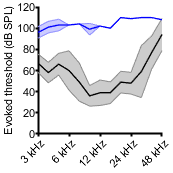

c = shadedErrorBar(freq,conMean,conSTD);
c.mainLine.LineWidth = 1;
hold on
c = shadedErrorBar(freq,conMeanp11,conSTDp11,'lineprops','b');
c.mainLine.LineWidth = 1;
ylim([0 120])
xlim([1 13])
ylabel(ylbl,'FontSize',8);
xticks([1 4 7 10 13]);
xticklabels({'3 kHz','6 kHz','12 kHz','24 kHz','48 kHz'})
xtickangle([45])
figQuality(gcf,gca,[1.8 1.8])

%print(gcf,'-dpdf')


genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5',};
mousecko = {'M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11','12','13'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 130×4 table
    Genotype    Mouse     Location    BW 
    ________    ______    ________    ___

    {'con'}     {'M1'}     {'1' }      72
    {'con'}     {'M1'}     {'2' }      75
    {'con'}     {'M1'}     {'3' }      77
    {'con'}     {'M1'}     {'4' }      73
    {'con'}     {'M1'}     {'5' }      54
    {'con'}     {'M1'}     {'6' }      33
    {'con'}     {'M1'}     {'7' }      32
    {'con'}     {'M1'}     {'8' }      30
    {'con'}     {'M1'}     {'9' }      40
    {'con'}     {'M1'}     {'10'}      39
    {'con'}     {'M1'}     {'11'}      40
    {'con'}     {'M1'}     {'12'}      80
    {'con'}     {'M1'}     {'13'}     108
    {'con'}     {'M2'}     {'1' }      72
    {'con'}     {'M2'}     {'2' }      55
    {'con'}     {'M2'}     {'3' }      57


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)')  

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             130
    Fixed effects coefficients           2
    Random effects coefficients         23
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1036.2    1050.6    -513.12          1026.2  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)' }            57       3.844    14.828    128    1.4293e-29    49.394    64.606
    {'Genotype_cko'}        47.231      4.3243    10.922    128    4.9865e-20    38.674    55.787

Random effects covariance parameters (95% CIs):
Group: Location (13 Levels)
    Name1                  Name2                  Type           Es

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    57.0000
   47.2308


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }            57       3.844    14.828     17.63    2.1459e-11    48.912    65.088
    {'Genotype_cko'}        47.231      4.3243    10.922    9.7049    9.1004e-07    37.556    56.906




cx261db0 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 393-1

cx262db0 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 393-3

cx263db0 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; % 418-2

